Right, so, firstly, using Poiseuille's law, $Q=\frac{\Delta p\pi D^4 }{128\mu \;L}$.

Secondly, ideal gas equation $\textrm{PV}=\textrm{mRT}$. Similarly, $P=\rho \text{ }\mathrm{RT}\to \rho =\frac{P}{\mathrm{RT}}=\frac{V}{m}$.

The volume of the cylinder changes as a function of time. Being a single-inlet system, the mass is also a function of time and the system is transient.

So, let $V\left(t\right)$ and $m\left(t\right)$be a function of time and the process be isothermal, then pressure inside the cylinder is given by ideal gas equation $P\left(t\right)=m\left(t\right)\frac{\textrm{RT}}{V\left(t\right)}$.

Identifying the system as a single inlet no outlet system, we obtain $Q=\frac{\text{dm}}{\text{dt}}$.

So, $\frac{\text{dm}}{\text{dt}}=\frac{\pi D^4 }{128\mu \text{ }L}\cdot \left(P_{\text{atm}} -\frac{m\left(t\right)}{V\left(t\right)}\text{RT}\right)$.

Here, $V\left(t\right)$is defined function of time.

Assume atmospheric conditions.

atm=101325;
R=8314/28;
T=298;
D=0.01;
mu=1.81e-5;
L=0.1;

figure(1)
clf
V(0:0.1:15)

ans = 0.1000

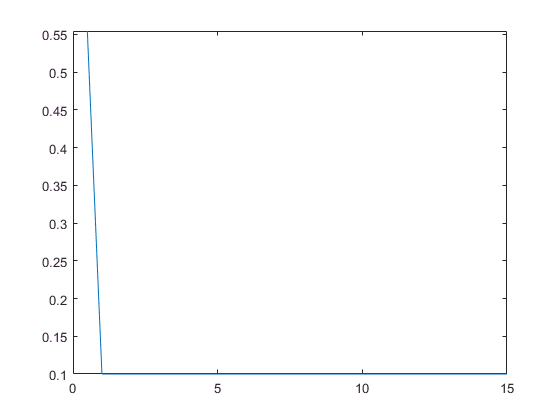

fplot(@V, [0 15])

Hit it: solve the equation.

[tt,y]=ode45(@(t,y)pi*D.^4/128/mu/L * (atm - y*R*T/V(t)) ,[0 15], double([atm*V(0)/R/T]));

The plotting section.

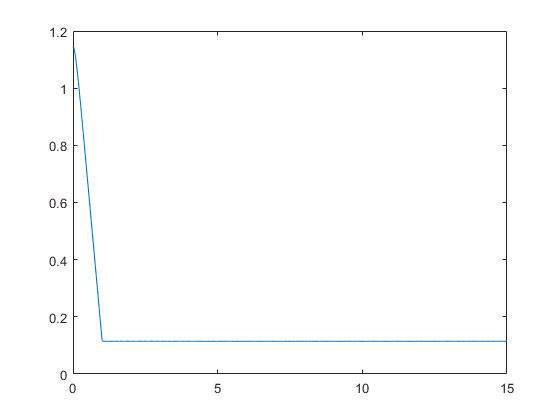

figure(2)
clf
plot(tt, y)

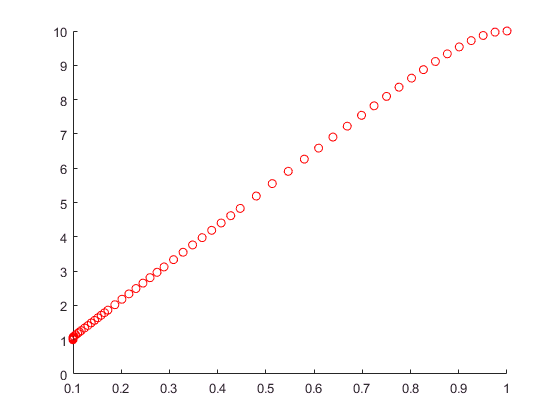

figure(3)
clf
hold on
PP=y/V(tt)*R*T;
for i=1:size(tt,1)
plot(V(tt(i)),PP(i)/atm,'ro')
end

Define function V(t)

function Vo=V(t)
    if t<1
         Vo=1-0.9*t;
    else 
         Vo=0.1;
    end
end